# 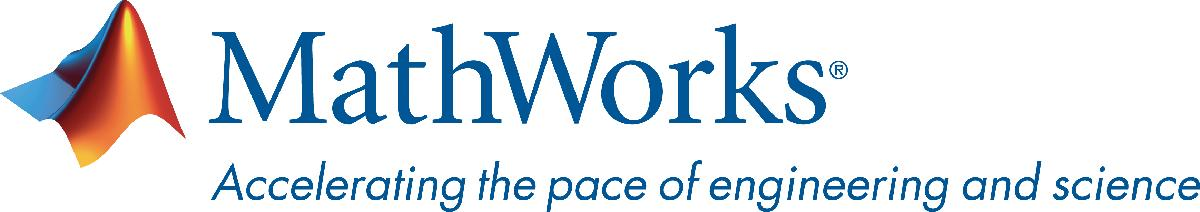

# Tutorial of Model-Based Security Threat and Risk Analysis - Introduction

In this tutorial, you will learn how to analyze your embedded system for security threats, estimate risks, and eventually implement countermeasures to improve your system's resilience against cyberattacks. This example shows a simplified security analysis for a warehouse robot, and has been presented at [MATLAB Expo](https://www.matlabexpo.com/) 2024.

## Prerequisites

For this tutorial to work you either need to use MATLAB Online or if you using a desktop installation make sure is at least release R2024b Update 1.

The following products are needed in order for this example to function correctly: 

- MATLAB®

- Simulink®

- System Composer™

- Simulink Fault Analyzer™

- Requirements Toolbox™

- Stateflow®

- Navigation Toolbox™

## Tutorial Content

The steps below is what we will cover within this tutorial:

- [Asset Identification](matlab:open('Tutorial_Step01_Asset')) - what needs to be protected?

- [Threat identification](matlab:open('Tutorial_Step02_Threat')) - how could the asset be attacked?

- [Estimate feasibility and impact](matlab:open('Tutorial_Step03_Feasibility_Impact')) - how bad would it be, and how hard would it be be to perform the attack?

- [Risk estimation and treatment](matlab:open('Tutorial_Step04_Risk')) - do we need to address the threat, and if yes how?

- [Allocating security goals ](matlab:open('Tutorial_Step05_SecurityGoal'))- define a set of security requirements to implement the countermeasure(s).

- [Validation](matlab:open('Tutorial_Step06_Validation')) - did we miss anything? Is the analysis complete?

- [Implementing countermeasures](matlab:open('Tutorial_Step07_Countermeasure')) - we show how we can implement one of the countermeasures.

- [Verification](matlab:open('Tutorial_Step08_Verify')) - we test the effectiveness of the countermeasure by simulating a cyberattack.

- [Updating the threat analysis](matlab:open('Tutorial_Step09_Changes')) - what happens if the threat landscape and/or the design changes?

- [Generate a report](matlab:open('Tutorial_Step10_Reporting')) - we show how we can export a simple report to store or archive your risk assessment.

- [Customization](matlab:open('Tutorial_Step11_Customization')) - learn how to modify every aspect of the threat and risk model, to customize it for your needs.

- [Resources](matlab:open('Tutorial_Step99_Resources')) - learn about additional reading materials, templates and webinars.

This process is aligned, but not specific to, the international standard [SAE J3061](https://www.sae.org/standards/content/j3061_202112/).

## Preparation

The system system that we will be using during this tutorial is a warehouse robot. A warehouse robot is a machine which automatically transports, sorts and arranges goods within a warehouse. It improves efficiency, accuracy, and safety. These robots are typically equipped with various technologies such as sensors, cameras, and software algorithms that allow them to navigate, pick and place boxes.

[Click here](matlab:open('WareHouseTaskRobotSimulationModel.slx')) or run the following command to open the system architecture:

open_system("WareHouseTaskRobotSimulationModel")

As shown in the figure below, the robot receives commands from a control center, and position data from cameras that are attached to the warehouse ceiling. We also have a "Robot Plant" which utilizes a simple kinematic model of a two-wheeled robot, characterized by the state ($ x=[x,y,\theta]$) and control inputs ($ u=[v,\omega] $)

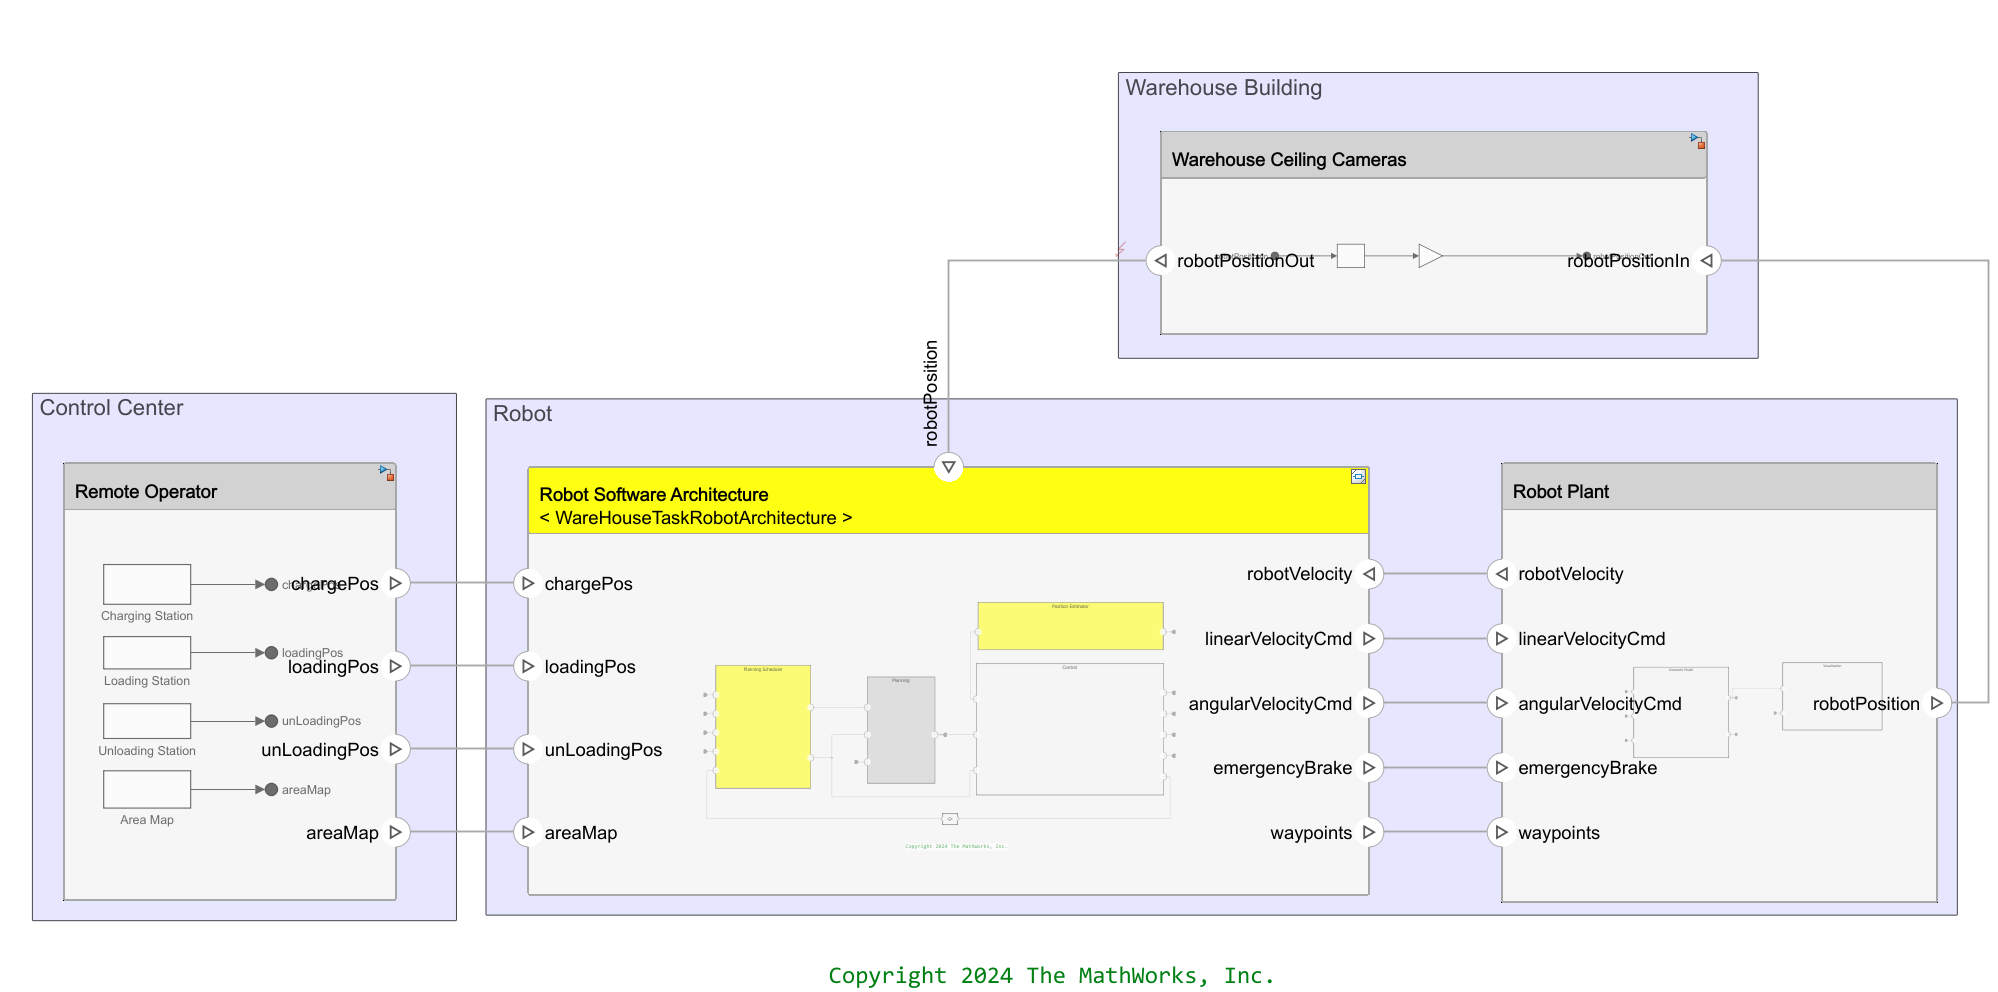

The robot itself contains the following components ([click here](matlab:open_system("WareHouseTaskRobotArchitecture")) or double-click on "Robot Software Architecture" to see):

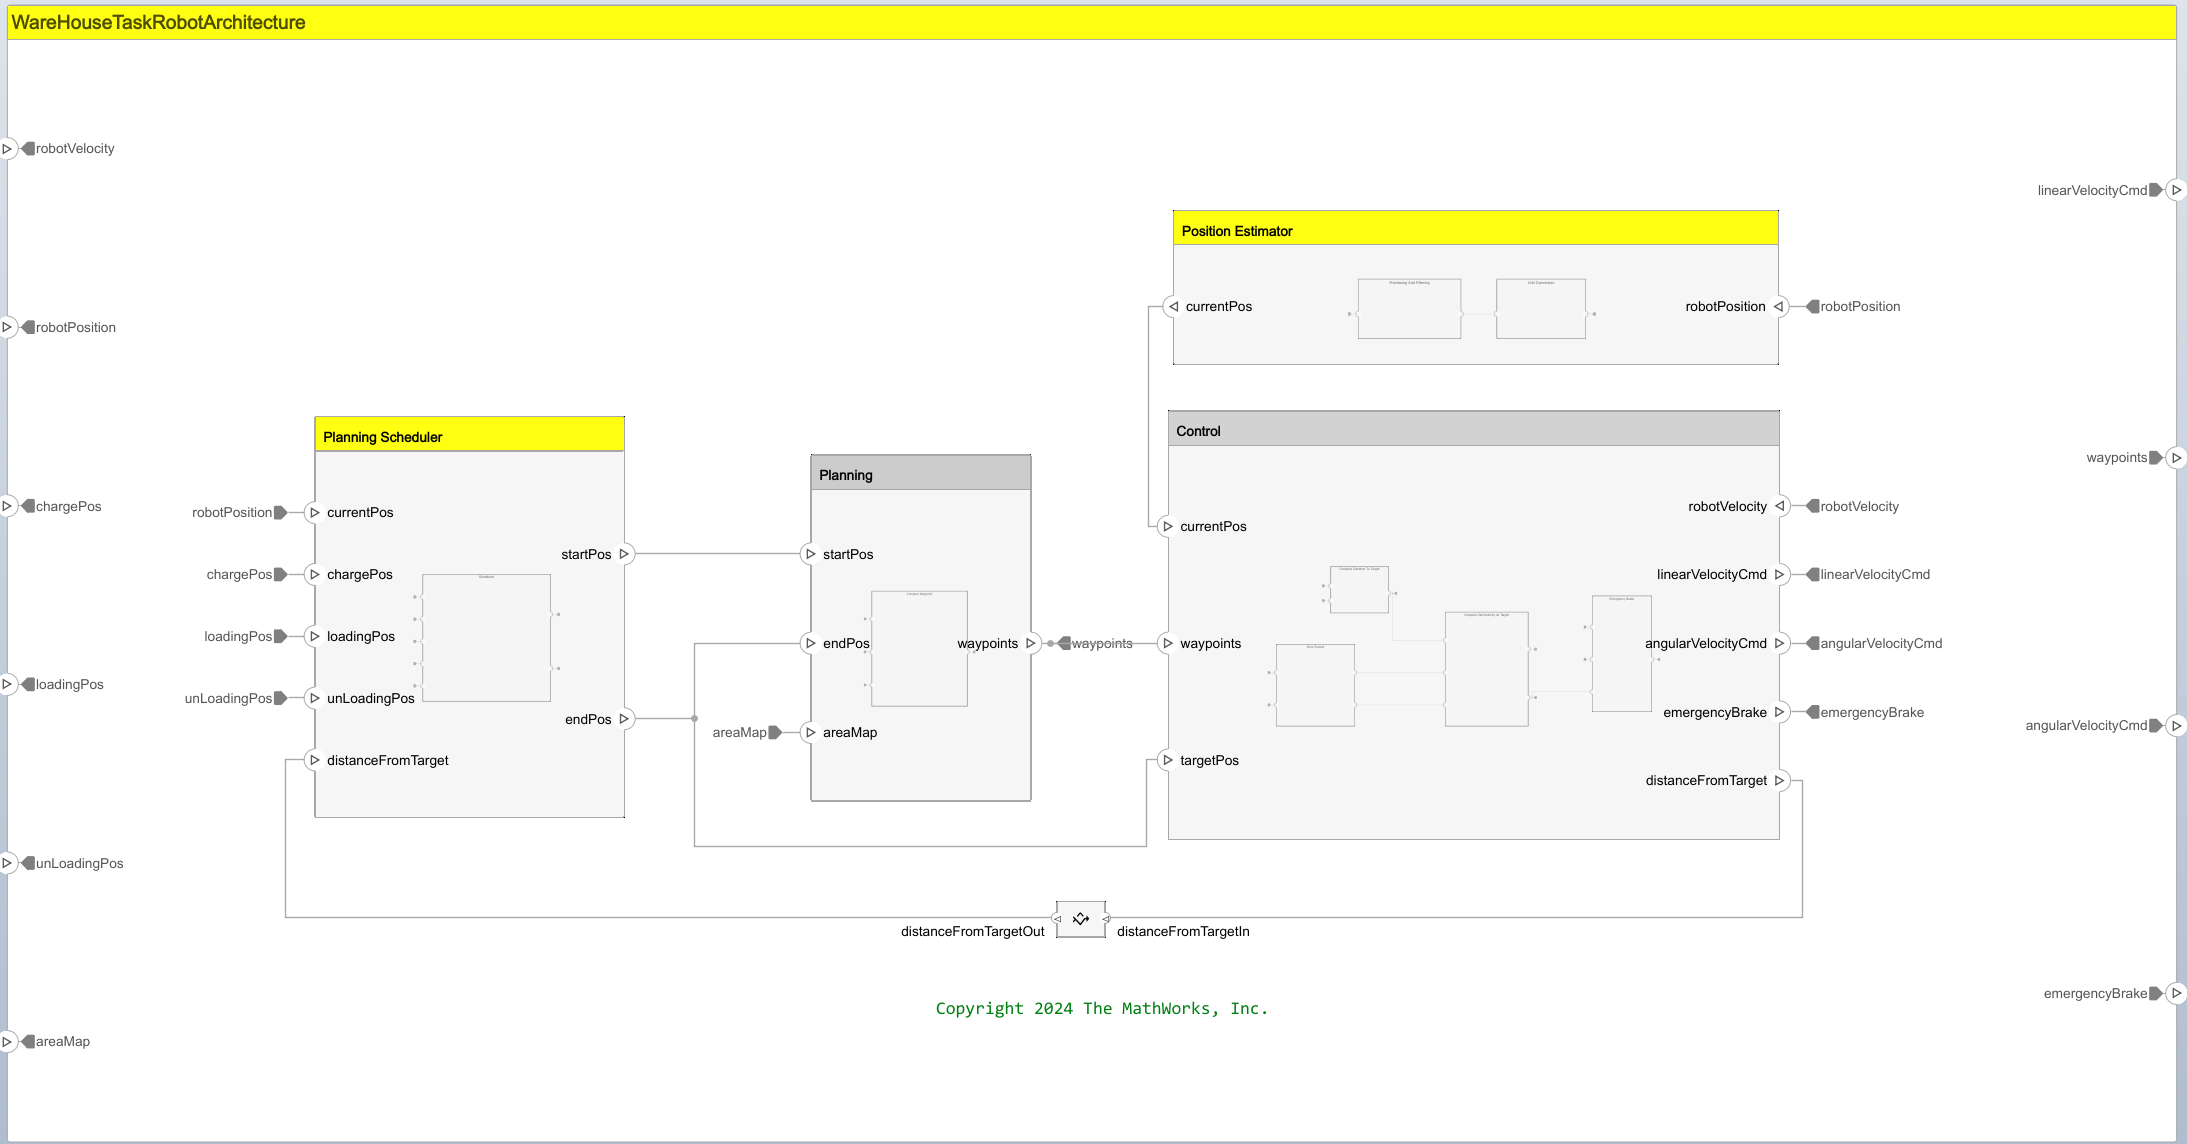

- [Planning Scheduler](matlab:hilite_system('WareHouseTaskRobotArchitecture/Planning Scheduler'))**:** decides the current operating mode of the robot - loading (and where), unloading (and where), charging or in between. It has a standardized network interface to accept commands from the control center.

- [Planning](matlab:hilite_system('WareHouseTaskRobotArchitecture/Planning'))**:** computes waypoints to go from A to B without running into obstacles.

- [Control](matlab:hilite_system('WareHouseTaskRobotArchitecture/Control'))**:** controls the actuators to follow the computed waypoints.

- [Position Estimator](matlab:hilite_system('WareHouseTaskRobotArchitecture/Position Estimator'))**:** estimates the robot's current coordinates in space, based on external inputs like the ceiling camera and additional sensors like LIDAR.

## Let's get started

Go to the first step - [Asset Identification](matlab:open('Tutorial_Step01_Asset')).